# F-16A Level 3 Sizing Analysis — Class-Based Example

This live script performs a Fidelity Level 3 sizing pass for the F-16A example using the toolkit classes supplied with the project. This version captures the W_TO value returned by SizingClassLevel3.size_aircraft().

Main objects used: * AircraftDesign * GeometryLevel3 * AeroLevel3 * PropulsionLevel3 * WeightLevel3 * MissionAnalysisLevel3 * ConstraintAnalysisClass * Requirements * SizingClassLevel3 * SubsystemsLevel3 optional fuel-volume check * SandCLevel3 optional static-stability check

The script assumes the corresponding class files, import utilities, design workbook, requirements table, constraints table, mission profile, and Stability&Control sheet are on the MATLAB path.

clear; close all;

## Project setup

Set this to the folder containing your classes, import utilities, design spreadsheet/workbook, requirements file, constraints file, mission data, and Stability&Control data.

projectRoot = pwd;
addpath(projectRoot);

% Change these names only if your local files use different names.
designName       = "F-16A Block 50";
requirementsName = "Requirements";
constraintsName  = "Constraints";
missionName      = "CAP";

## Create the aircraft design object

AircraftDesign is the project-level object. It imports the design geometry, fuselage data, propulsion data, weight data, general aircraft data, and requirements reference.

design = AircraftDesign( ...
     designName, ...
     RequirementsName = requirementsName, ...
     ConstraintsName  = constraintsName, ...
     AutoLoad         = true);


disp("AircraftDesign object created:")

AircraftDesign object created:


disp(design)

  AircraftDesign with properties:

                     Name: "F-16A Block 50"
                     geom: [1×1 struct]
                  general: [1×1 struct]
               propulsion: [1×1 struct]
          propulsion_type: "low bpr turbofan"
                n_engines: []
                 CivOrMil: []
                     role: []
                  weights: [1×1 struct]
                     type: "Jet fighter"
              wing_config: []
              tail_config: []
            fuselage_type: []
               nose_shape: []
             requirements: [1×1 struct]
    requirements_filename: []
     constraints_filename: "Constraints"
            WeightResults: []
              AeroResults: []
        PropulsionResults: []
           internalvolume: []


## Build the Level 3 analysis objects

Level 3 uses textbook/component methods. GeometryLevel3 loads component geometry and wetted areas, AeroLevel3 performs component drag buildup, PropulsionLevel3 uses dry/wet thrust and TSFC lapse equations, WeightLevel3 performs component/subsystem empty-weight buildup, MissionAnalysisLevel3 evaluates the mission fuel profile, and SizingClassLevel3 closes W_TO.

% Consider relegating each instantiation to separate blocks
% Include explanatory text; purpose, outputs, design variables
% Recall most aircraft variables are continuous, but can be grouped.

## Weight

weight_obj       = F16WeightLevel3(design);

% Initialize some things
weight_obj.W_fixed = design.weights.Weights.Fixedlbf;
weight_obj.W_TO_guess = design.weights.Weights.WTO_guess;
weight_obj.K_vs = design.weights.Coefficients.Kvs;
% aircraft_type = "fighter";
% weight_obj.wings = weight_obj.get_wing_weight(aircraft_type, geometry_obj.mainwings.S_exposed);
% weight_obj.HT = weight_obj.get_HT_weight(aircraft_type, geometry_obj.HT.S_exposed);
% weight_obj.VT = weight_obj.get_VT_weight(aircraft_type, geometry_obj.VT.S_exposed);
% weight_obj.fuselage = weight_obj.get_fuselage_weight(aircraft_type, geometry_obj.fuselage.S_wet);
% weight_obj.landinggear = weight_obj.get_landinggear_weight(aircraft_type, false, weight_obj.W_TO_guess);
% weight_obj.engine = weight_obj.get_eng_installed_weight(aircraft_type, design.propulsion.Weight.Dry);
weight_obj.W_TO_guess = 45000; % lbf

## Geometry

geometry_obj     = F16GeometryLevel3(design);

delta_flap_TO = 20; % Flap setting during takeoff (deg)
delta_flap_L = 60; % Flap setting during landing (deg)
cf_c = (-33 + 34.08)/geometry_obj.mainwings.c_root; % numerator comes from TE flap geometry in Brandt's "F16" excel file (Sheet = "Main")
cp_c = (17.78 - (34.08 - 32))/(geometry_obj.mainwings.c_root); % Numerator comes from main wing's longitudinal anchor point - distance between TE flap's root's TE and LE.
geometry_obj.S_flapped = GeometryUtils.S_trapezoid(13.08, 7.08, 7.75); % Equation comes from NASA. (Try using Roskam's equation, 7.10, next time).
hld_w_TE_HL = atand(1/7.75); % numerator = x-distance between foremost outboard and inboard points, denominator = y-distance between those same 2 points.


% Purpose:
% Initializes object for storing and manipulating design geometry
% variables.

% Variables:
% Main wings: b, c_root, c_tip, t/c
% Horizontal tail: b, c_root, c_tip, t/c
% Vertical tail: b, c_root, c_tip, t/c
% Strakes: b, c_root, c_tip, t/c
% Fuselage: length, width, max height, diameter.
% Used to calculate reference area, taper ratio, aspect ratio, wetted, and
% exposed areas of lifting surfaces.

% Outputs:
% Design geometry object
% S_ref, lambda, AR, S_wet, S_exposed

## Aerodynamics

aero_obj         = F16AeroLevel3();
% aero_obj.CL_minD = 0.02843; % Hardcoded from Brandt.

% Set some variables
% Initialize some things
% aero_obj.airfoiltype = "cambered";


% Get e_osw_clean
aero_obj.e_osw_clean = aero_obj.get_e_osw(geometry_obj.mainwings.AR, geometry_obj.mainwings.LE_sweep);

% Get e_osw_L
a = AeroLevel1.Delta_CD0(3,3); % Extract the "landing_flaps" row from Delta_CD0 table
b = a.e_osw{1}; % Extract the e_osw column
c = max(b); % Extract the highest value
aero_obj.e_osw_L = (aero_obj.e_osw_clean + c)/2; % Take the average because I can't think of a better way.

% Get e_osw_TO
a = AeroLevel1.Delta_CD0(2,3); % Extract the "takeoff_flaps" row from Delta_CD0 table
b = a.e_osw{1}; % Extract the e_osw column
c = max(b); % Extract the highest value
aero_obj.e_osw_TO = (aero_obj.e_osw_clean + c)/2; % Take the average because I can't think of a better way.

% Get K
aero_obj.K = 1/(pi*aero_obj.e_osw_clean*geometry_obj.mainwings.AR);

% Get Delta_CD0_TO
aero_obj.Delta_CD0_TO = aero_obj.get_Delta_CD0(aero_obj.hld_TE, cf_c, geometry_obj.S_flapped, geometry_obj.mainwings.S_ref, aero_obj.delta_hld_TE_TO);

% Get Delta_CD0_Landing
aero_obj.Delta_CD0_L = aero_obj.get_Delta_CD0(aero_obj.hld_TE, cf_c, geometry_obj.S_flapped, geometry_obj.mainwings.S_ref, aero_obj.delta_hld_TE_L);

% Get Delta_CD0_geardown
aero_obj.Delta_CD0_geardown = aero_obj.get_Delta_CD0_L();

% Get Cf
% aero_obj.Cf = aero_obj.get_Cf("air force fighter", 1);

% Compute CD0
% CD0 = aero_obj.get_CD0(aero_obj, geometry_obj.design.S_wet, geometry_obj.mainwings.S_ref);


% Get CL_max_base
% Done (in F16AeroLevel2, line 41 (Properties (Constant)))

% Get Delta_cl_max_TO
aero_obj.Delta_cl_max_TO = aero_obj.get_Delta_cl_max_values(aero_obj.hld_TE, "takeoff", cp_c);

% Get Delta_cl_max_L
aero_obj.Delta_cl_max_L = aero_obj.get_Delta_cl_max_values(aero_obj.hld_TE, "landing", cp_c);

% Get Delta_CL_max_TO
aero_obj.Delta_CL_max_TO = aero_obj.get_Delta_CL_max_values(aero_obj.Delta_cl_max_TO, geometry_obj.S_flapped, geometry_obj.mainwings.S_ref, hld_w_TE_HL);

% Get Delta_CL_max_L
aero_obj.Delta_CL_max_L = aero_obj.get_Delta_CL_max_values(aero_obj.Delta_cl_max_L, geometry_obj.S_flapped, geometry_obj.mainwings.S_ref, hld_w_TE_HL);

% Get CL_max_clean
aero_obj.CL_max_clean = aero_obj.get_CL_max_values(geometry_obj.mainwings.AR, geometry_obj.mainwings.LE_sweep, aero_obj.CL_max_base, 0, aero_obj.cl_max, aero_obj.CL_max_cl_max);

% Get CL_max_TO
aero_obj.CL_max_TO = aero_obj.get_CL_max_values(geometry_obj.mainwings.AR, geometry_obj.mainwings.LE_sweep, aero_obj.CL_max_base, aero_obj.Delta_CL_max_TO, aero_obj.cl_max, aero_obj.CL_max_cl_max);

% Get CL_max_L
aero_obj.CL_max_L = aero_obj.get_CL_max_values(geometry_obj.mainwings.AR, geometry_obj.mainwings.LE_sweep, aero_obj.CL_max_base, aero_obj.Delta_CL_max_L, aero_obj.cl_max, aero_obj.CL_max_cl_max);

% Get CL_max_clean
% aero_obj.CL_max_clean = aero_obj.get_CL_max_values(geometry_obj.mainwings.AR, geometry_obj.mainwings.LE_sweep, aero_obj.CL_max_base, 0, aero_obj.cl_max, aero_obj.CL_max_cl_max);

% Get fuselage lift factor
aero_obj.F = aero_obj.get_F(geometry_obj.fuselage.W_max, geometry_obj.mainwings.b);

% Purpose:
% Initializes object for storing and manipulating aerodynamic data.

% Variables:
% Design geometry

% Outputs:
% Aerodynamics object
% CL, CD, CDi, CD0, CD_wave

## Requirements

requirements_obj = Requirements(design);

% Purpose:
% Initializes object for storing and manipulating design requirements.

% Variables:
% Max mach: h_alt, M, g's
% Cruise condition: h_alt, M, afterburner percent
% Loiter condition: h_alt, time
% Payload: weight
% Combat condition: h_alt, M, g's, AB percent, n_turns
% Specific excess power: h_alt, Mach number, g's, AB percent, specific excess power required
% Takeoff/landing: h_alt, distance

% Outputs:
% Design requirements object

## Propulsion

propulsion_obj = F16PropulsionLevel3(requirements_obj, design);

% Purpose:
% Initiallizes object for storing and manipulating properties of the
% engine. Estimates performance characteristics based on inputs.

% Variables:
%

% Outputs:
% Propulsion object
% Design's engine characteristics
% TSFC, thrust, engine geometry

## Mission

mission_obj = F16MissionAnalysisLevel3(missionName);

% Purpose:
% Initializes object containing data for each mission segment, and computes
% fuel burned for the entire provided mission.

% Properties:
% Mission data - per-segment data: altitude, airspeed
% fuel_burned: sum of fuel burned throughout mission

% Outputs:
% Mission object
% Missiondata
% fuel_burned

## Constraints

We require constraints like "optimum wing-loading" and "minimum T/W" for sizing computations. So we'll initialize them, here.

constraint_obj   = F16ConstraintAnalysis();
% Need to update the aerodynamic constraints for each given constraint
% (altitude, mach number)

% Get table of state vectors (mach number, altitude) for each constraint
% (constraint name)
constraints_table = Import_Constraints(constraintsName);

constraints_length = length(constraints_table.Altitude_ft_)

constraints_length = 8


alpha_max = 15;
n = alpha_max;
alpha_array = linspace(-alpha_max, alpha_max, n);

% Load up miscellaneous constraints
beta = constraints_table.W_Wto;
n = constraints_table.n;
mu = constraints_table.SurfaceFrictionCoefficient_mu_;
Ps = constraints_table.PS_ft_s_;
distance = constraints_table.Distance_ft_;

% Clean up inputs before things get messy
Ps(isnan(Ps)==1)=0;
n(isnan(n)==1)=0;
distance(isnan(distance)==1)=0;
mu(isnan(mu)==1)=0;


% Get the Mach number and altitude
M = constraints_table.MachNumber;
h_alt = constraints_table.Altitude_ft_;
state_vector = [M, h_alt];

% Set up geometry stuff
AR = geometry_obj.mainwings.AR;
LE_sweep_deg = geometry_obj.mainwings.LE_sweep;
Cf = aero_obj.Cf; % Compute this
S_wet = geometry_obj.get_design_S_wet(weight_obj.W_TO_guess);
S_ref = geometry_obj.mainwings.S_ref;
% e_osw = aero_obj.e_osw;
T_SL_dry = propulsion_obj.T_SL_dry;
T_SL_wet = propulsion_obj.T_SL_wet;
gamma = 1.4;

W_S = constraint_obj.Wto_S_range;

% Get density at sea level
[T, a, P, rho_SL] = atmosisa(0);

% Convert rho_SL to slugs
rho_SL = rho_SL*0.00194032033; % Convert from kg/m^3 -> imperial units

for i=1:constraints_length
     % Clean up input.
     current_constraint = constraints_table.Row{i}
     AB_percent = constraints_table.AB_(i);

     if isnan(AB_percent)==true
          AB_percent = 1.0;
     elseif (AB_percent > 1.0)
          AB_percent = AB_percent/100;
     elseif (0.0 < AB_percent < 1.0)
          % Do nothing
     else
          error("Error handler.") % Just in case something weird happens.
     end

     % Set up aerodynamic state.
     M = state_vector(i,1);
     h_alt = state_vector(i,2);
     statevector = [M, h_alt];

     % Get density at current altitude
     [T, a, P, rho] = atmosisa(h_alt*0.3048);

     % Convert rho to slugs
     rho = rho*0.00194032033; % Convert from kg/m^3 -> imperial units

     % Convert a to ft/s
     a = a*3.2808399;

     % The easier solution would be to just compute this for every constraint
     % condition.
     if (current_constraint == "Takeoff")
          % Do takeoff calculations
          % V = 168; % Hardcoded takeoff velocity (ft/s)
          for k=1:length(W_S)
               V_stall = AeroUtils.V_stall(W_S(k), aero_obj.CL_max_TO, rho)
               V_TO = 1.2*V_stall;
               M_TO = V_TO./a;

               takeoff_statevector = [M_TO, h_alt];

               % Get CL_minD
               % aero_obj.CL_minD = 0.02843; % Hardcoded from Brandt
               % Need CL_min

               % Get cl_alpha (2-D) for the constraint
               cl_alpha = aero_obj.get_cl_alpha(takeoff_statevector(1));
               % cl_alpha = cl_alpha/57.3; % Convert to cl_alpha per degree

               % Get CL_alpha
               CL_alpha = aero_obj.get_CL_alpha(takeoff_statevector(1), cl_alpha, geometry_obj.mainwings.AR, geometry_obj.mainwings.S_exposed, geometry_obj.mainwings.S_ref, aero_obj.F, geometry_obj.mainwings.QC_sweep);
               % CL_alpha = CL_alpha/57.3; % Convert from radians to degree

               % Get CL_minD
               aero_obj.CL_minD = aero_obj.get_CL_minD(CL_alpha, aero_obj.alpha_L0); % We are computing CL_minD per constraint because cl_alpha is a function of Mach number... which changes per constraint condition.

               % Get q
               q_TO = AeroUtils.q(takeoff_statevector);

               % Get CL as a function of aerodynamic properties
               CL_aero = aero_obj.CL(weight_obj.W_TO_guess, q_TO, geometry_obj.mainwings.S_ref);

               % Get CL as a function of AOA
               CL_AOA = (CL_alpha/57.3).*(aero_obj.alpha_L0 - alpha_array);

               % Get CD0 for takeoff
               CD0_TO = aero_obj.get_CD0(takeoff_statevector, design, geometry_obj, geometry_obj.mainwings.S_ref, propulsion_obj);
               CD0_TO = CD0 + aero_obj.Delta_CD0_TO + aero_obj.Delta_CD0_geardown;

               % Get CD_min
               CD_min = CD0_TO;

               % Get CD
               CD = aero_obj.get_CD(CD0_TO, CDi, CL_AOA, aero_obj.CL_minD, "cambered", takeoff_statevector, K1);

               % Get K1 & K2
               [K1_TO, K2_TO] = aero_obj.get_K(AR, aero_obj.e_osw_TO, M_TO, LE_sweep_deg, aero_obj.CL_minD);
               % [aero_obj.e_osw_TO, CD0, V, q] = constraint_obj.get_aero_constraints(takeoff_statevector, aero_obj.e_osw_TO, Cf, S_wet, S_ref)

               [alpha_TO, alpha_dry_TO, alpha_wet_TO] = constraint_obj.get_thrust_constraints(takeoff_statevector, T_SL_dry, T_SL_wet, gamma, AB_percent, propulsion_obj)

               aero_constraints_TO(k, :) = [aero_obj.e_osw_TO, K1_TO, K2_TO, CD0_TO, V_TO, q_TO];
               thrust_constraints_TO(k, :) = [alpha_TO, alpha_dry_TO, alpha_wet_TO];
          end
          e_osw_TO = aero_constraints_TO(:,1);
          K1_TO = aero_constraints_TO(:,2);
          K2_TO = aero_constraints_TO(:,3);
          V_TO = aero_constraints_TO(:,5);
          % q_takeoff = aero_constraints_takeoff(:,6);

          alpha_TO = thrust_constraints_TO(:,1);
          alpha_dry_TO = thrust_constraints_TO(:,2);
          alpha_wet_TO = thrust_constraints_TO(:,3);
     elseif (current_constraint == "Landing")
          % Do landing calculations
          for k=1:length(W_S)
               V_stall = AeroUtils.V_stall(W_S(k), aero_obj.CL_max_L, rho)
               V_L = 1.3*V_stall;
               M_L = V_L./a;

               landing_statevector = [M_L, h_alt];

               % Get CL_minD
               % aero_obj.CL_minD = 0.02843; % Hardcoded from Brandt
               % Need CL_min
               % Thought: If the 2-D lift coefficient can change if flaps
               % are/aren't deployed, then I should definitely factor that
               % into the calculations.

               % Get cl_alpha (2-D) for the constraint
               cl_alpha = aero_obj.get_cl_alpha(landing_statevector(1));
               % cl_alpha = cl_alpha/57.3; % Convert to cl_alpha per degree

               % Get CL_alpha
               CL_alpha = aero_obj.get_CL_alpha(landing_statevector(1), cl_alpha, geometry_obj.mainwings.AR, geometry_obj.mainwings.S_exposed, geometry_obj.mainwings.S_ref, aero_obj.F, geometry_obj.mainwings.QC_sweep);
               % CL_alpha = CL_alpha/57.3; % Convert from radians to degree

               % Get CL_minD
               aero_obj.CL_minD = aero_obj.get_CL_minD(CL_alpha, aero_obj.alpha_L0); % We are computing CL_minD per constraint because cl_alpha is a function of Mach number... which changes per constraint condition.

               % Get q
               q_L = AeroUtils.q(landing_statevector);

               % Get CL as a function of aerodynamic properties
               CL_aero = aero_obj.CL(weight_obj.W_TO_guess, q_L, geometry_obj.mainwings.S_ref);

               % Get CL as a function of AOA
               CL_AOA = (CL_alpha/57.3).*(aero_obj.alpha_L0 - alpha_array);

               % Get CD0
               CD0_L = aero_obj.get_CD0(landing_statevector, design, geometry_obj, geometry_obj.mainwings.S_ref, propulsion_obj);
               CD0_L = CD0 + aero_obj.Delta_CD0_L + aero_obj.Delta_CD0_geardown;

               % Get CD_min
               CD_min = CD0_L;

               % Get CD
               CD = aero_obj.get_CD(CD0_L, CDi, CL_AOA, aero_obj.CL_minD, "cambered", landing_statevector, K1);

               % Get K1 & K2
               [K1_L, K2_L] = aero_obj.get_K(AR, aero_obj.e_osw_L, M_L, LE_sweep_deg, aero_obj.CL_minD);

               [alpha_L, alpha_dry_L, alpha_wet_L] = constraint_obj.get_thrust_constraints(landing_statevector, T_SL_dry, T_SL_wet, gamma, AB_percent, propulsion_obj)

               % thrust_constraints(i, :) = [0, 0, 0];
               % aero_constraints(i, :) = [0, 0, 0, 0, 0, 0];
               aero_constraints_L(k, :) = [aero_obj.e_osw_L, K1_L, K2_L, CD0_L, V_L, q_L];
               thrust_constraints_L(k, :) = [alpha_L, alpha_dry_L, alpha_wet_L];
          end
          e_osw_L = aero_constraints_L(:,1);
          K1_L = aero_constraints_L(:,2);
          K2_L = aero_constraints_L(:,3);
          V_L = aero_constraints_L(:,5);
          q_L = aero_constraints_L(:,6);

          alpha_L = thrust_constraints_L(:,1);
          alpha_dry_L = thrust_constraints_L(:,2);
          alpha_wet_L = thrust_constraints_L(:,3);
     else


          % Get CL_minD
          % aero_obj.CL_minD = 0.02843; % Hardcoded from Brandt
          % Need CL_min

          % Get cl_alpha (2-D) for the constraint
          cl_alpha = aero_obj.get_cl_alpha(statevector(1));
          % cl_alpha = cl_alpha/57.3; % Convert to cl_alpha per degree

          % Get CL_alpha
          CL_alpha = aero_obj.get_CL_alpha(statevector(1), cl_alpha, geometry_obj.mainwings.AR, geometry_obj.mainwings.S_exposed, geometry_obj.mainwings.S_ref, aero_obj.F, geometry_obj.mainwings.QC_sweep);
          % CL_alpha = CL_alpha/57.3; % Convert from radians to degree

          % Get CL_minD
          aero_obj.CL_minD = aero_obj.get_CL_minD(CL_alpha, aero_obj.alpha_L0); % We are computing CL_minD per constraint because cl_alpha is a function of Mach number... which changes per constraint condition.
          aero_obj.CL_minD = aero_obj.CL_minD/57.3;

          % Get q
          q = AeroUtils.q(statevector);

          % Get CL as a function of aerodynamic properties
          CL_aero = aero_obj.CL(weight_obj.W_TO_guess, q, geometry_obj.mainwings.S_ref);

          % Get CL as a function of AOA
          CL_AOA = (CL_alpha/57.3).*(aero_obj.alpha_L0 - alpha_array);

          % Get CD0
          CD0 = aero_obj.get_CD0(statevector, design, geometry_obj, geometry_obj.mainwings.S_ref, propulsion_obj);

          % Get CD_min
          CD_min = CD0;

          % Get CDi
          alpha = 0;
          statevector(3) = alpha;
          CDi = aero_obj.get_CDi(statevector, geometry_obj.mainwings.S_ref, aero_obj.e_osw_clean, geometry_obj.mainwings.AR, weight_obj.W_TO_guess);

          % Get K1, K2
          [K1, K2] = aero_obj.get_K(AR, aero_obj.e_osw_clean, M, LE_sweep_deg, aero_obj.CL_minD)


          % Get CD
          CD = aero_obj.get_CD(CD0, CDi, CL_AOA, aero_obj.CL_minD, "cambered", statevector, K1);

          % Compute thrust constraints (alpha_dry, alpha_wet, alpha)
          [alpha, alpha_dry, alpha_wet] = constraint_obj.get_thrust_constraints(statevector, T_SL_dry, T_SL_wet, gamma, AB_percent, propulsion_obj)

          % Compute thrust at altitude (sanity check)
          T_alt_wet = PropulsionUtils.thrust_from_lapse(alpha_wet, T_SL_wet)
          T_alt_dry = PropulsionUtils.thrust_from_lapse(alpha_dry, T_SL_dry)

          thrust_constraints(i, :) = [alpha, alpha_dry, alpha_wet];

          % Casey, you REALLY need to clean this up!!!
          aero_obj.e_osw_clean = aero_obj.get_e_osw(AR, geometry_obj.mainwings.LE_sweep);
          % [K1, K2] = aero_obj.get_K(AR, aero_obj.e_osw_clean, M, LE_sweep_deg, aero_obj.CL_minD)
          V = AeroUtils.compute_airspeed(statevector);
          q = AeroUtils.q(statevector);
          % [aero_obj.e_osw_clean, CD0, V, q] = constraint_obj.get_aero_constraints([M, h_alt], aero_obj.e_osw_clean, aero_obj.Cf, S_wet, S_ref)
          aero_constraints(i, :) = [aero_obj.e_osw_clean, K1, K2, CD0, V, q];
     end
end

current_constraint = 'Max Mach'

K1 = 0.2760

K2 = 0

alpha = 0.5494

alpha_dry = 0.3089

alpha_wet = 0.5494

T_alt_wet = 1.3060e+04

T_alt_dry = 4.6332e+03

current_constraint = 'Cruise'

K1 = 0.1168

K2 = -0.0064

alpha = 0.1391

alpha_dry = 0.2204

alpha_wet = 0.3674

T_alt_wet = 8.7330e+03

T_alt_dry = 3.3066e+03

current_constraint = 'Max Alt'

K1 = 0.1168

K2 = -0.0064

alpha = 0.1875

alpha_dry = 0.1125

alpha_wet = 0.1875

T_alt_wet = 4.4559e+03

T_alt_dry = 1.6871e+03

current_constraint = 'Combat Subsonic'

K1 = 0.1168

K2 = -0.0064

alpha = 0.7526

alpha_dry = 0.4516

alpha_wet = 0.7526

T_alt_wet = 1.7890e+04

T_alt_dry = 6.7738e+03

current_constraint = 'Combat Supersonic'

K1 = 0.2261

K2 = 0

alpha = 0.6007

alpha_dry = 0.3546

alpha_wet = 0.6007

T_alt_wet = 1.4278e+04

T_alt_dry = 5.3187e+03

current_constraint = 'Excess Power'

K1 = 0.1168

K2 = -0.0064

alpha = 0.8608

alpha_dry = 0.5028

alpha_wet = 0.8608

T_alt_wet = 2.0462e+04

T_alt_dry = 7.5426e+03

current_constraint = 'Takeoff'

V_stall = 111.6074

alpha_TO = 1.0000

alpha_dry_TO = 0.5995

alpha_wet_TO = 1.0000

V_stall = 129.6761

alpha_TO = 0.9999

alpha_dry_TO = 0.5993

alpha_wet_TO = 0.9999

V_stall = 145.5183

alpha_TO = 0.9999

alpha_dry_TO = 0.5990

alpha_wet_TO = 0.9999

V_stall = 159.7975

alpha_TO = 0.9998

alpha_dry_TO = 0.5988

alpha_wet_TO = 0.9998

V_stall = 172.9015

alpha_TO = 0.9998

alpha_dry_TO = 0.5986

alpha_wet_TO = 0.9998

V_stall = 185.0800

alpha_TO = 0.9997

alpha_dry_TO = 0.5984

alpha_wet_TO = 0.9997

V_stall = 196.5052

alpha_TO = 0.9996

alpha_dry_TO = 0.5981

alpha_wet_TO = 0.9996

V_stall = 207.3016

alpha_TO = 0.9996

alpha_dry_TO = 0.5979

alpha_wet_TO = 0.9996

V_stall = 217.5629

alpha_TO = 0.9995

alpha_dry_TO = 0.5977

alpha_wet_TO = 0.9995

V_stall = 227.3616

alpha_TO = 0.9994

alpha_dry_TO = 0.5974

alpha_wet_TO = 0.9994

V_stall = 236.7551

alpha_TO = 0.9993

alpha_dry_TO = 0.5971

alpha_wet_TO = 0.9993

V_stall = 245.7899

alpha_TO = 0.9991

alpha_dry_TO = 0.5969

alpha_wet_TO = 0.9991

V_stall = 254.5041

alpha_TO = 0.9990

alpha_dry_TO = 0.5966

alpha_wet_TO = 0.9990

V_stall = 262.9297

alpha_TO = 0.9989

alpha_dry_TO = 0.5963

alpha_wet_TO = 0.9989

V_stall = 271.0935

alpha_TO = 0.9987

alpha_dry_TO = 0.5960

alpha_wet_TO = 0.9987

V_stall = 279.0186

alpha_TO = 0.9986

alpha_dry_TO = 0.5957

alpha_wet_TO = 0.9986

V_stall = 286.7247

alpha_TO = 0.9984

alpha_dry_TO = 0.5955

alpha_wet_TO = 0.9984

V_stall = 294.2290

alpha_TO = 0.9982

alpha_dry_TO = 0.5951

alpha_wet_TO = 0.9982

V_stall = 301.5467

alpha_TO = 0.9980

alpha_dry_TO = 0.5948

alpha_wet_TO = 0.9980

V_stall = 308.6909

alpha_TO = 0.9978

alpha_dry_TO = 0.5945

alpha_wet_TO = 0.9978

V_stall = 315.6735

alpha_TO = 0.9976

alpha_dry_TO = 0.5942

alpha_wet_TO = 0.9976

current_constraint = 'Landing'

V_stall = 108.3039

alpha_L = 1.0000

alpha_dry_L = 0.5994

alpha_wet_L = 1.0000

V_stall = 125.8378

alpha_L = 0.9999

alpha_dry_L = 0.5992

alpha_wet_L = 0.9999

V_stall = 141.2110

alpha_L = 0.9999

alpha_dry_L = 0.5989

alpha_wet_L = 0.9999

V_stall = 155.0676

alpha_L = 0.9998

alpha_dry_L = 0.5987

alpha_wet_L = 0.9998

V_stall = 167.7837

alpha_L = 0.9997

alpha_dry_L = 0.5984

alpha_wet_L = 0.9997

V_stall = 179.6017

alpha_L = 0.9997

alpha_dry_L = 0.5982

alpha_wet_L = 0.9997

V_stall = 190.6887

alpha_L = 0.9996

alpha_dry_L = 0.5979

alpha_wet_L = 0.9996

V_stall = 201.1656

alpha_L = 0.9995

alpha_dry_L = 0.5977

alpha_wet_L = 0.9995

V_stall = 211.1232

alpha_L = 0.9994

alpha_dry_L = 0.5974

alpha_wet_L = 0.9994

V_stall = 220.6318

alpha_L = 0.9992

alpha_dry_L = 0.5971

alpha_wet_L = 0.9992

V_stall = 229.7473

alpha_L = 0.9991

alpha_dry_L = 0.5968

alpha_wet_L = 0.9991

V_stall = 238.5146

alpha_L = 0.9989

alpha_dry_L = 0.5965

alpha_wet_L = 0.9989

V_stall = 246.9709

alpha_L = 0.9988

alpha_dry_L = 0.5962

alpha_wet_L = 0.9988

V_stall = 255.1471

alpha_L = 0.9986

alpha_dry_L = 0.5958

alpha_wet_L = 0.9986

V_stall = 263.0693

alpha_L = 0.9984

alpha_dry_L = 0.5955

alpha_wet_L = 0.9984

V_stall = 270.7598

alpha_L = 0.9982

alpha_dry_L = 0.5952

alpha_wet_L = 0.9982

V_stall = 278.2378

alpha_L = 0.9980

alpha_dry_L = 0.5948

alpha_wet_L = 0.9980

V_stall = 285.5200

alpha_L = 0.9978

alpha_dry_L = 0.5945

alpha_wet_L = 0.9978

V_stall = 292.6211

alpha_L = 0.9976

alpha_dry_L = 0.5941

alpha_wet_L = 0.9976

V_stall = 299.5538

alpha_L = 0.9973

alpha_dry_L = 0.5938

alpha_wet_L = 0.9973

V_stall = 306.3297

alpha_L = 0.9971

alpha_dry_L = 0.5934

alpha_wet_L = 0.9971


% Build tables for aero constraints
aero_constraints_table = array2table(aero_constraints, "VariableNames",{'e_osw', 'K1', 'K2', 'CD0', 'V', 'q'}, "RowNames", {'Max Mach', 'Cruise', 'Max Alt', 'Combat Subsonic', 'Combat Supersonic', 'Excess Power'})

aero_constraints_table = 6×6 table
                          e_osw       K1           K2          CD0         V         q   
                         _______    _______    __________    ________    ______    ______
    Max Mach             0.90862    0.27603             0     0.23984    1549.6    850.68
    Cruise               0.90862    0.11677    -0.0063939    0.071708    842.57    251.52
    Max Alt              0.90862    0.11677    -0.0063939    0.046116    842.23    128.33
    Combat Subsonic      0.90862    0.11677    -0.0063939     0.10757    902.06    515.26
    Combat Supersonic    0.90862     0.2261             0     0.24586    1355.9     651.3
    Excess Power         0.90

e_osw = aero_constraints(:,1);
K1 = aero_constraints(:,2);
K2 = aero_constraints(:,3);
CD0 = aero_constraints(:,4);
V = aero_constraints(:,5);
q = aero_constraints(:,6);

% Build table for thrust constraints
thrust_constraints_table = array2table(thrust_constraints, "VariableNames",{'alpha', 'alpha_dry', 'alpha_wet'}, "RowNames", {'Max Mach', 'Cruise', 'Max Alt', 'Combat Subsonic', 'Combat Supersonic', 'Excess Power'})

thrust_constraints_table = 6×3 table
                          alpha     alpha_dry    alpha_wet
                         _______    _________    _________
    Max Mach             0.54943     0.30888      0.54943 
    Cruise               0.13911     0.22044       0.3674 
    Max Alt              0.18746     0.11247      0.18746 
    Combat Subsonic      0.75265     0.45159      0.75265 
    Combat Supersonic    0.60067     0.35458      0.60067 
    Excess Power         0.86082     0.50284      0.86082 

alpha = thrust_constraints(:,1);
alpha_dry = thrust_constraints(:,2);
alpha_wet = thrust_constraints(:,3);

% Compute T/W and wing loading stuff for all constraints
TW_table = constraint_obj.createThrustLoadingTable(aero_constraints_table, beta, alpha, n, q, V, CD0, K1, Ps, W_S)

TW_table =    18.5770   13.7665   10.9383    9.0769    7.7594    6.7781    6.0191    5.4148    4.9225    4.5138    4.1691    3.8747    3.6204    3.3985    3.2034    3.0305    2.8763    2.7380    2.6133    2.5002    2.3974
    6.5367    4.8749    3.9052    3.2730    2.8308    2.5059    2.2587    2.0654    1.9113    1.7863    1.6837    1.5987    1.5276    1.4679    1.4175    1.3749    1.3388    1.3083    1.2825    1.2607    1.2426
    1.6571    1.2754    1.0621    0.9311    0.8463    0.7901    0.7528    0.7286    0.7140    0.7065    0.7044    0.7066    0.7122    0.7205    0.7312    0.7437    0.7578    0.7732    0.7899    0.8075    0.8259
    3.7808    2.8607    2.3337    1.9985    1.7711    1.6104    1.4938    1.4078    1.3441    1.2969    1.2624    1.2379    1.2214    1.2113    1.2065    1.2061    1.2094    1.2158    1.2250    1.2364    1.2499
   13.3475    9.8982    7.8719    6.5396    5.5978    4.8974    4.3566    3.9268    3.5774    3.2880    3.0446    2.8372    2.6587    2.5034    2



% Takeoff and landing analysis
% CALCULATIONS

T_Wto_takeoff = ConstraintAnalysisClass.takeoff_constraint(W_S, 1.2, beta(7), alpha_TO', rho, aero_obj.CL_max_TO, distance(7), CD0_TO, mu(7))

T_Wto_takeoff =     0.1853    0.2097    0.2341    0.2585    0.2829    0.3073    0.3317    0.3561    0.3806    0.4050    0.4294    0.4539    0.4783    0.5028    0.5273    0.5518    0.5763    0.6008    0.6253    0.6499    0.6744


Wto_S_Landing = ConstraintAnalysisClass.landing_constraint(distance(8), beta(8), rho, aero_obj.CL_max_L, CD0_L, mu(8))

Wto_S_Landing = 157.6535




% Package the aero and thrust results into a table format to use the
% pre-existing graph functions.
new_constraints_array = [aero_constraints, thrust_constraints];
new_constraints_table = array2table(new_constraints_array, "VariableNames",{'e_osw', 'K1', 'K2', 'CD0', 'V', 'q', 'alpha', 'alpha_dry', 'alpha_wet'}, "RowNames", {'Max Mach', 'Cruise', 'Max Alt', 'Combat Subsonic', 'Combat Supersonic', 'Excess Power'})

new_constraints_table = 6×9 table
                          e_osw       K1           K2          CD0         V         q        alpha     alpha_dry    alpha_wet
                         _______    _______    __________    ________    ______    ______    _______    _________    _________
    Max Mach             0.90862    0.27603             0     0.23984    1549.6    850.68    0.54943     0.30888      0.54943 
    Cruise               0.90862    0.11677    -0.0063939    0.071708    842.57    251.52    0.13911     0.22044       0.3674 
    Max Alt              0.90862    0.11677    -0.0063939    0.046116    842.23    128.33    0.18746 


% Trim takeoff and landing from constraints table
% constraints_table = [constraints_table, new_constraints_table]

% Get optimal wing loading and T/W
[constraint_obj.optimal_WS, constraint_obj.min_TW] = constraint_obj.solveOptimalPoint(TW_table, T_Wto_takeoff, W_S)

constraint_obj =   F16ConstraintAnalysis with properties:

          Wto_S_range: [20 27 34 41 48 55 62 69 76 83 90 97 104 111 118 125 132 139 146 153 160]
             TW_table: []
        T_Wto_takeoff: []
           optimal_WS: 160
               min_TW: 2.3974
        Wto_S_landing: []
             W0_S_ref: []
       T_Wto_required: [18.5770 13.7665 10.9383 9.0769 7.7594 6.7781 6.0191 5.4148 4.9225 4.5138 4.1691 3.8747 3.6204 3.3985 3.2034 3.0305 2.8763 2.7380 2.6133 2.5002 2.3974]
    constraints_table: []

constraint_obj =   F16ConstraintAnalysis with properties:

          Wto_S_range: [20 27 34 41 48 55 62 69 76 83 90 97 104 111 118 125 132 139 146 153 160]
             TW_table: []
        T_Wto_takeoff: []
           optimal_WS: 160
               min_TW: 2.3974
        Wto_S_landing: []
             W0_S_ref: []
       T_Wto_required: [18.5770 13.7665 10.9383 9.0769 7.7594 6.7781 6.0191 5.4148 4.9225 4.5138 4.1691 3.8747 3.6204 3.3985 3.2034 3.0305 2.8763 2.7380 2.6133 2.5002 2.3974]
    constraints_table: []

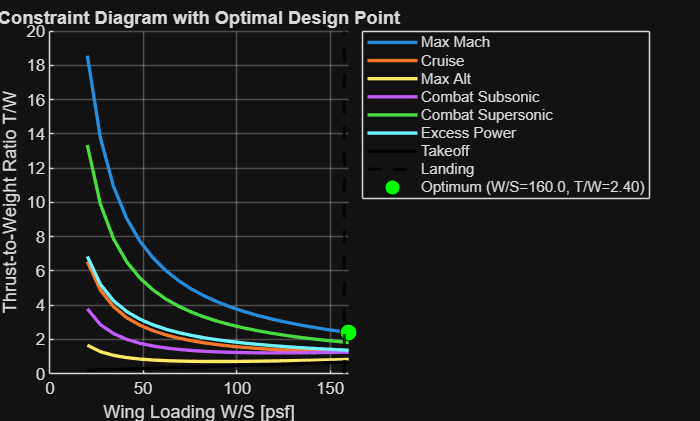


constraint_obj.plotConstraintDiagram(W_S, TW_table, T_Wto_takeoff, Wto_S_Landing, constraint_obj.optimal_WS, constraint_obj.min_TW, {constraints_table.Row{:}})

## Sizing

sizing_obj       = F16SizingLevel3();

% Purpose:
% Explicitly for sizing the aircraft.

% Variables:
% Design geometry, design propulsion, mission segment data, aerodynamic
% data, constraint data, requirements, weight of components

% Outputs:
% Design MTOW

## Run the project sizing class

This calls your SizingClassLevel3 method directly and captures the returned takeoff gross weight. The sizing class still displays its internal iteration table. A persistent trace is reconstructed in the next section for plots and reporting.

results_table = sizing_obj.compute_TOGW( ...
     design, ...
     geometry_obj, ...
     mission_obj, ...
     weight_obj, ...
     propulsion_obj, ...
     constraint_obj, ...
     requirements_obj, ...
     aero_obj);
disp(results_table)

     WTO     W_fixed    Fuel_fraction    Empty_weight_fraction    Empty_weight    WTO_new    Difference     Percent_Diff    S_ref_w (ft^2)    S_ref_ht (ft^2)    S_ref_vt (ft^2)
    _____    _______    _____________    _____________________    ____________    _______    ___________    ____________    ______________    _______________    _______________
    45000     5100         0.27505              0.46447              20901         37678         -7322.2        -16.272          300                108              59.976     
    37678     5100         0.26876              0.52196              19666         34320       

%
% fprintf("\nSizingClassLevel3 returned W_TO = %.3f lbf.\n", W_TO_fromSizingClass);
% fprintf("Plot sections below read from the Level 3 object properties populated by the sizing run.\n");

## Optional subsystem fuel-volume check

SubsystemsLevel3 estimates internal volume and fuel volume using the current geometry and the final fuel weight. This is a diagnostic check; it is not part of the sizing convergence loop above.

subsystemSummary = table();
if exist('SubsystemsLevel3', 'class') == 8 || exist('SubsystemsLevel3.m', 'file') == 2
     try
          % Use the fuel burn already stored on weight_obj by MissionAnalysisLevel3.
          subsystems_obj = SubsystemsLevel3(geometry_obj, weight_obj, design);
          fuelVolumeOK = subsystems_obj.checkfuelvol(subsystems_obj.internal_volume, subsystems_obj.fuel_volume);

          subsystemSummary = table( ...
               subsystems_obj.internal_volume, ...
               subsystems_obj.fuel_volume, ...
               fuelVolumeOK, ...
               'VariableNames', {'InternalVolume_gal', 'FuelVolumeRequired_gal', 'IsFuelVolumeSufficient'});

          disp("Optional Level 3 subsystem/fuel-volume summary:")
          disp(subsystemSummary)
     catch ME
          warning("SubsystemsLevel3 check was skipped: %s", ME.message);
     end
end

Optional Level 3 subsystem/fuel-volume summary:


    InternalVolume_gal    FuelVolumeRequired_gal    IsFuelVolumeSufficient
    __________________    ______________________    ______________________
          11276                   1230.2                    true          


## Optional longitudinal static-stability check

SandCLevel3 needs component weights and x-locations. This script attempts to extract those from the Stability&Control data loaded by SandCUtils. If the layout cannot be inferred, it skips the static-stability call and tells you where to enter the vectors manually.

stabilitySummary = table();
if exist('SandCLevel3', 'class') == 8 || exist('SandCLevel3.m', 'file') == 2
     try
          sandc_obj = SandCLevel3(design);
          [component_weight_list, component_weight_x_locations, stabilityInputTable] = ...
               tryBuildSandCInputs(sandc_obj.weightlocations);

          if isempty(component_weight_list) || isempty(component_weight_x_locations)
               warning("%s", ...
                    "Could not automatically infer component weight and x-location vectors from sandc_obj.weightlocations. " + ...
                    "Edit component_weight_list and component_weight_x_locations manually in this section to run the static-stability check.");
          else
               disp("Static-stability component inputs inferred from sandc_obj.weightlocations:")
               disp(stabilityInputTable)

               cruiseState = [ ...
                    mission_obj.missiondata.Cruise.MachNumber, ...
                    mission_obj.missiondata.Cruise.Altitudeft, ...
                    0, ...
                    weight_obj.W_TO];

               i_w = 0;
               epsilon = 0;

               [SM, StabilityResults] = sandc_obj.get_static_margin( ...
                    geometry_obj, ...
                    aero_obj, ...
                    design, ...
                    cruiseState, ...
                    component_weight_list, ...
                    component_weight_x_locations, ...
                    i_w, ...
                    epsilon);

               stabilitySummary = struct2tableForDisplay(StabilityResults);
               disp("Optional Level 3 static-stability summary:")
               disp(stabilitySummary)
          end
     catch ME
          warning("SandCLevel3 static-stability check was skipped: %s", ME.message);
     end
end

Static-stability component inputs inferred from sandc_obj.weightlocations:


      Component       Weight_lbf    XLocation_ft
    ______________    __________    ____________
    "Wing"               1785          27.28    
    "Fuselage"           3652             26    
    "HT"                  648             41    
    "VT"                  360             40    
    "Nacelles"            186             29    
    "Strakes"              90             17    
    "Engine"             4730             33    
    "Gear"               1066             26    
    "InletDuct"           728             22    
    "Controls"            472             27    
    "Electrical"          533             33    
    "Hydraulics"          367             33    
    "ECS"                 360             27    
    "Other"              2016             20    
    "Avionics"           2541             15    
    "Armaments"           440             26    
    "FixedPayloa

## Formal Optimization Formulation

% There's no code here.

Minimize: $W_{\textrm{fuel}\;\textrm{burned}}$

with respect to:

     Wings: $b,c_{\textrm{root}} ,c_{\textrm{tip}} ,\left(\frac{t}{c}\right)$

     Fuselage: $L_{\textrm{fus}} ,D_{\textrm{fus}}$

subject to the following constraints:

     Design constriants: $S_{\textrm{Takeoff}} ,S_{\textrm{Landing}} ,V_{\textrm{stall}}$

     Mission parameters: $R_{\textrm{cruise}} ,E_{\textrm{loiter}} ,V_{\textrm{cruise}} ,V_{\textrm{loiter}}$

     Performance requirements: $\textrm{PS},\psi ,M_{\max } ,h_{\textrm{ceiling}} ,\textrm{roc}$

     Subsystem requirements: ${\textrm{Vol}}_{\textrm{fuel}}$

     Handling characteristics: $\textrm{SM}$

## Plot gross-weight convergence

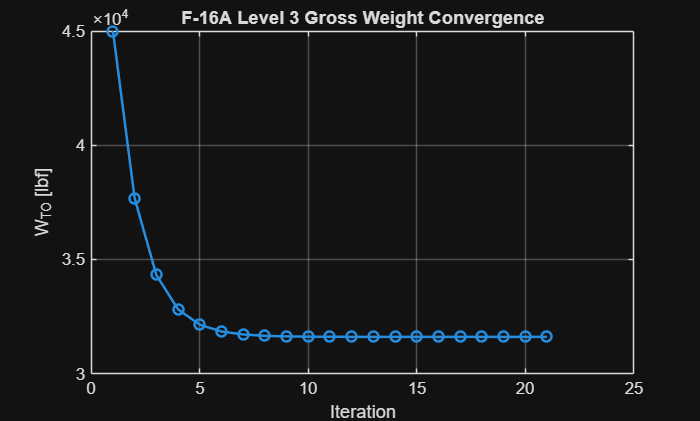

figure('Name', 'Level 3 Gross Weight Convergence');
iterationIdx = 1:height(sizing_obj.results_table);
plot(iterationIdx, sizing_obj.results_table.WTO, '-o', 'LineWidth', 1.5);
grid on;
xlabel('Iteration');
ylabel('W_{TO} [lbf]');
title('F-16A Level 3 Gross Weight Convergence');

% Source: sizing_obj.results_table populated by SizingClassLevel3.

## Plot closure error

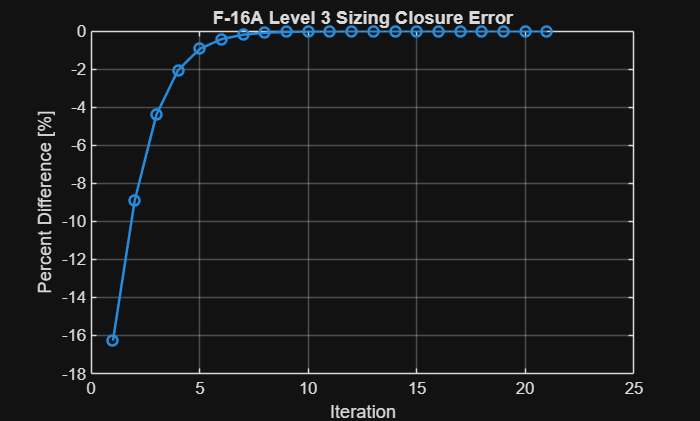

figure('Name', 'Level 3 Closure Error');
iterationIdx = 1:height(sizing_obj.results_table);
plot(iterationIdx, sizing_obj.results_table.Percent_Diff, '-o', 'LineWidth', 1.5);
grid on;
xlabel('Iteration');
ylabel('Percent Difference [%]');
title('F-16A Level 3 Sizing Closure Error');

% Source: sizing_obj.results_table populated by SizingClassLevel3.

## Plot final weight breakdown

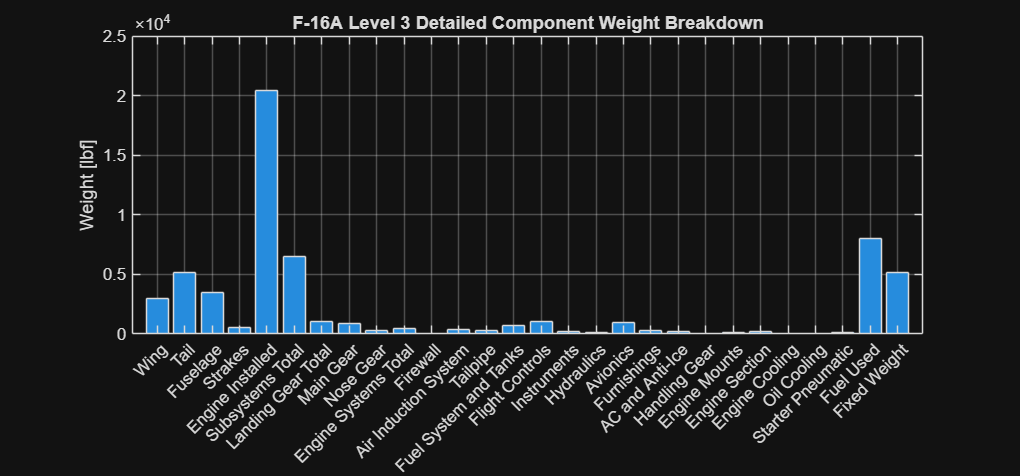

% Detailed component/subsystem weight breakdown.
% Uses the already-populated Level 3 weight object and the current design
% coefficient table. Subcomponents that are not stored directly on
% weight_obj.subsystems are reconstructed here from the same Raymer-style
% equations used by WeightLevel3.subsystem_weight_III.

subsystems = weight_obj.subsystems;
if isstruct(weight_obj.OEW) && isfield(weight_obj.OEW, "W_subsystems")
     subsystems = weight_obj.OEW.W_subsystems;
end

coeff = design.weights.Coefficients;

W_engine_total = getScalarField(weight_obj.engine, "W_total", NaN);
W_engine_installed = getScalarField(weight_obj.engine, "W_installed", 1.3*W_engine_total);

% Landing gear subcomponents.
W_main_gear = getScalarField(subsystems, "W_main_gear", NaN);
W_nose_gear = getScalarField(subsystems, "W_nose_gear", NaN);
if isnan(W_main_gear)
     W_main_gear = getScalarField(coeff, "Kcb", NaN) * getScalarField(coeff, "Ktpg", NaN) * ...
          (getScalarField(coeff, "Wl", NaN) * getScalarField(coeff, "Nl", NaN))^(0.25) * ...
          getScalarField(coeff, "Lm", NaN)^(0.973);
end
if isnan(W_nose_gear)
     W_nose_gear = (getScalarField(coeff, "Wl", NaN) * getScalarField(coeff, "Nl", NaN))^(0.290) * ...
          getScalarField(coeff, "Ln", NaN)^(0.5) * getScalarField(coeff, "Nnw", NaN)^(0.525);
end
W_landinggear_total = getScalarField(subsystems, "W_landinggear", W_main_gear + W_nose_gear);

% Engine-system subcomponents.
W_engine_mounts = getScalarField(subsystems, "W_engine_mounts", NaN);
W_engine_section = getScalarField(subsystems, "W_engine_section", NaN);
W_engine_cooling = getScalarField(subsystems, "W_engine_cooling", NaN);
W_oil_cooling = getScalarField(subsystems, "W_oil_cooling", NaN);
W_starter_pneumatic = getScalarField(subsystems, "W_starter_pneumatic", NaN);

if isnan(W_engine_mounts)
     W_engine_mounts = 0.013 * getScalarField(coeff, "Nen", NaN)^(0.795) * ...
          propulsion_obj.T0^(0.579) * getScalarField(coeff, "Nz", NaN);
end
if isnan(W_engine_section)
     W_engine_section = 0.01 * W_engine_installed^(0.717) * ...
          getScalarField(coeff, "Nen", NaN) * getScalarField(coeff, "Nz", NaN);
end
if isnan(W_engine_cooling)
     W_engine_cooling = 4.55 * getScalarField(coeff, "De", NaN) * ...
          getScalarField(coeff, "Lsh", NaN) * getScalarField(coeff, "Nen", NaN);
end
if isnan(W_oil_cooling)
     W_oil_cooling = 37.82 * getScalarField(coeff, "Nen", NaN)^(1.008) * ...
          getScalarField(coeff, "Lec", NaN)^(0.222);
end
if isnan(W_starter_pneumatic)
     W_starter_pneumatic = 0.025 * propulsion_obj.T0^(0.760) * ...
          getScalarField(coeff, "Nen", NaN)^(0.72);
end
W_engine_systems = getScalarField(subsystems, "W_engine_systems", ...
     W_engine_mounts + W_engine_section + W_engine_cooling + W_oil_cooling + W_starter_pneumatic);

% Detailed subsystem components.
W_firewall = getScalarField(subsystems, "W_firewall", 1.13 * getScalarField(coeff, "Sfw", NaN));
W_air_induction_system = getScalarField(subsystems, "W_air_induction_system", ...
     13.29 * getScalarField(coeff, "Kvg", NaN) * getScalarField(coeff, "Ld", NaN)^(0.643) * ...
     getScalarField(coeff, "Kd", NaN)^(0.182) * getScalarField(coeff, "Nen", NaN)^(0.1498) * ...
     (getScalarField(coeff, "Ls", NaN)/getScalarField(coeff, "Ld", NaN))^(-0.373) * ...
     getScalarField(coeff, "De", NaN));
W_tailpipe = getScalarField(subsystems, "W_tailpipe", ...
     3.5 * getScalarField(coeff, "De", NaN) * getScalarField(coeff, "Ltp", NaN) * getScalarField(coeff, "Nen", NaN));
W_fuelsystem_and_tanks = getScalarField(subsystems, "W_fuelsystem_and_tanks", ...
     7.45 * getScalarField(coeff, "Vt", NaN)^(0.47) * ...
     (1 + getScalarField(coeff, "Vi", NaN)/getScalarField(coeff, "Vt", NaN))^(-0.095) * ...
     (1 + getScalarField(coeff, "VP", NaN)/getScalarField(coeff, "Vt", NaN)) * ...
     getScalarField(coeff, "Nt", NaN)^(0.066) * getScalarField(coeff, "Nen", NaN)^(0.052) * ...
     (propulsion_obj.T0 * getScalarField(coeff, "SFC", NaN)/1000)^(0.249));
W_flight_controls = getScalarField(subsystems, "W_flight_controls", ...
     36.28 * getScalarField(coeff, "M", NaN)^(0.003) * getScalarField(coeff, "Scs", NaN)^(0.489) * ...
     getScalarField(coeff, "Ns", NaN)^(0.484) * getScalarField(coeff, "Nc", NaN)^(0.127));
W_instruments = getScalarField(subsystems, "W_instruments", ...
     8.0 + 36.37 * getScalarField(coeff, "Nen", NaN)^(0.676) * getScalarField(coeff, "Nt", NaN)^(0.237) + ...
     26.4 * (1 + getScalarField(coeff, "Nci", NaN))^(1.356));
W_hydraulics = getScalarField(subsystems, "W_hydraulics", ...
     37.23 * getScalarField(coeff, "Kvsh", NaN) * getScalarField(coeff, "Nu", NaN)^(0.664));
W_avionics = getScalarField(subsystems, "W_avionics", ...
     2.117 * getScalarField(coeff, "Wuav", NaN)^(0.933));
W_furnishings = getScalarField(subsystems, "W_furnishings", ...
     217.6 * getScalarField(coeff, "Nc", NaN));
W_AC_and_antiice = getScalarField(subsystems, "W_AC_and_antiice", ...
     201.6 * ((getScalarField(coeff, "Wuav", NaN) + 200 * getScalarField(coeff, "Nc", NaN))/1000)^(0.735));
W_handling_gear = getScalarField(subsystems, "W_handling_gear", ...
     3.2e-4 * weight_obj.W_TO);

weightBreakdownLabels = [ ...
     "Wing"; ...
     "Tail"; ...
     "Fuselage"; ...
     "Strakes"; ...
     "Engine Installed"; ...
     "Subsystems Total"; ...
     "Landing Gear Total"; ...
     "Main Gear"; ...
     "Nose Gear"; ...
     "Engine Systems Total"; ...
     "Firewall"; ...
     "Air Induction System"; ...
     "Tailpipe"; ...
     "Fuel System and Tanks"; ...
     "Flight Controls"; ...
     "Instruments"; ...
     "Hydraulics"; ...
     "Avionics"; ...
     "Furnishings"; ...
     "AC and Anti-Ice"; ...
     "Handling Gear"; ...
     "Engine Mounts"; ...
     "Engine Section"; ...
     "Engine Cooling"; ...
     "Oil Cooling"; ...
     "Starter Pneumatic"; ...
     "Fuel Used"; ...
     "Fixed Weight"];

weightBreakdown_lbf = [ ...
     getScalarField(weight_obj, "wings", getScalarField(weight_obj.OEW, "W_Wing", NaN)); ...
     getScalarField(weight_obj, "tail", getScalarField(weight_obj.OEW, "W_tail", NaN)); ...
     getScalarField(weight_obj, "fuselage", getScalarField(weight_obj.OEW, "W_fuselage", NaN)); ...
     getScalarField(weight_obj, "strakes", getScalarField(weight_obj.OEW, "W_strakes", NaN)); ...
     W_engine_installed; ...
     getScalarField(subsystems, "total", NaN); ...
     W_landinggear_total; ...
     W_main_gear; ...
     W_nose_gear; ...
     W_engine_systems; ...
     W_firewall; ...
     W_air_induction_system; ...
     W_tailpipe; ...
     W_fuelsystem_and_tanks; ...
     W_flight_controls; ...
     W_instruments; ...
     W_hydraulics; ...
     W_avionics; ...
     W_furnishings; ...
     W_AC_and_antiice; ...
     W_handling_gear; ...
     W_engine_mounts; ...
     W_engine_section; ...
     W_engine_cooling; ...
     W_oil_cooling; ...
     W_starter_pneumatic; ...
     weight_obj.total_fuel_used; ...
     weight_obj.W_fixed];

validWeightRows = isfinite(weightBreakdown_lbf) & ~isnan(weightBreakdown_lbf);
weightBreakdownLabels = weightBreakdownLabels(validWeightRows);
weightBreakdown_lbf = weightBreakdown_lbf(validWeightRows);
weightBreakdownComponents = categorical(weightBreakdownLabels, weightBreakdownLabels, 'Ordinal', true);

figure('Name', 'Level 3 Detailed Component Weight Breakdown', 'Position', [100 100 1500 700]);
bar(weightBreakdownComponents, weightBreakdown_lbf);
grid on;
ylabel('Weight [lbf]');
title('F-16A Level 3 Detailed Component Weight Breakdown');
xtickangle(45);

% Source: weight_obj.OEW, weight_obj.subsystems, weight_obj.engine,
% design.weights.Coefficients, weight_obj.total_fuel_used, weight_obj.W_fixed.

## Plot final mission fuel by segment

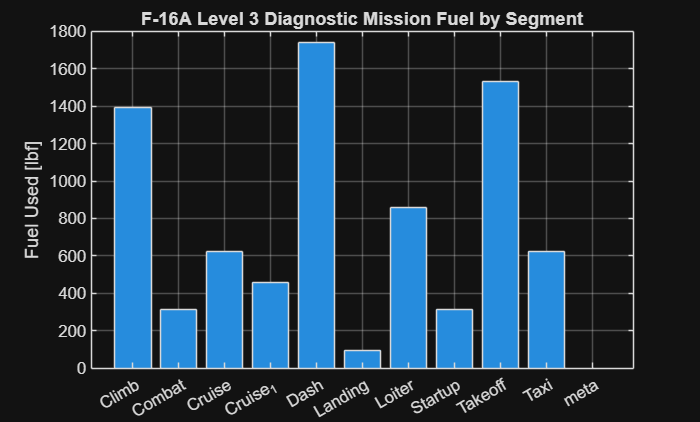

missionSegmentNames = string(fieldnames(mission_obj.missiondata));
missionFuel_lbf = mission_obj.mission_fuel(:);

% MissionAnalysisLevel3 stores one fuel-burn entry per missiondata field.
% Trim defensively in case a profile has an extra metadata field.
nMissionRows = min(numel(missionSegmentNames), numel(missionFuel_lbf));
missionSegmentNames = missionSegmentNames(1:nMissionRows);
missionFuel_lbf = missionFuel_lbf(1:nMissionRows);

figure('Name', 'Level 3 Mission Fuel by Segment');
bar(categorical(missionSegmentNames), missionFuel_lbf);
grid on;
ylabel('Fuel Used [lbf]');
title('F-16A Level 3 Diagnostic Mission Fuel by Segment');

% Source: mission_obj.mission_fuel populated by MissionAnalysisLevel3.

## Plot Level 3 aerodynamic snapshot

% Build mission-segment aerodynamic coefficient and force charts using the
% current F16AeroLevel3 object and mission data.
%
% Requested outputs:
%   1) Aerodynamic coefficients at each mission segment: CD, CDi, CD0, CD_wave
%   2) Aerodynamic values at each mission segment: Lift and Drag
%
% Notes:
%   * Startup/taxi/static rows are retained in the tables. If Mach/q is not
%     physically meaningful for a row, that row is plotted as NaN rather than
%     causing the live script to fail.
%   * F16AeroLevel3 rolls wave drag into supersonic CD0 internally, so
%     CD_wave is recomputed separately for the plot when M >= 1.2.

if ~isstruct(aero_obj.DragResults)
     aero_obj.DragResults = struct();
end

Unrecognized method, property, or field 'DragResults' for class 'F16AeroLevel3'.


airfoiltype = "cambered";
if isfield(geometry_obj.mainwings, "airfoil_type") && ~isempty(geometry_obj.mainwings.airfoil_type)
     airfoiltypeCandidate = string(geometry_obj.mainwings.airfoil_type);
     if ~isempty(airfoiltypeCandidate) && ~ismissing(airfoiltypeCandidate(1)) && strlength(airfoiltypeCandidate(1)) > 0
          airfoiltype = airfoiltypeCandidate(1);
     end
end

segmentFields = string(fieldnames(mission_obj.missiondata));

segmentNames = strings(0, 1);
M_list       = zeros(0, 1);
h_list       = zeros(0, 1);
CD_list      = zeros(0, 1);
CDi_list     = zeros(0, 1);
CD0_list     = zeros(0, 1);
CDwave_list  = zeros(0, 1);
CL_list      = zeros(0, 1);
Lift_list    = zeros(0, 1);
Drag_list    = zeros(0, 1);
Weight_list  = zeros(0, 1);

S_ref = geometry_obj.mainwings.S_ref;
AR    = geometry_obj.mainwings.AR;
e_osw = aero_obj.e_osw;

% Use the final sized W_TO as the starting segment weight. If mission fuel
% is available by segment, march weight approximately from segment to segment
% so lift/drag snapshots are based on the current mission weight instead of
% one constant W_TO for every row.
if exist('results_table', 'var') && istable(results_table) && height(results_table) > 0 && any(strcmp("WTO_new", string(results_table.Properties.VariableNames)))
     W_running = results_table.WTO_new(end);
elseif istable(sizing_obj.results_table) && height(sizing_obj.results_table) > 0 && any(strcmp("WTO_new", string(sizing_obj.results_table.Properties.VariableNames)))
     W_running = sizing_obj.results_table.WTO_new(end);
else
     W_running = weight_obj.W_TO;
end
missionFuelBySegment = [];
if isnumeric(mission_obj.mission_fuel)
     missionFuelBySegment = mission_obj.mission_fuel(:);
end
fuelIdx = 1;

for i = 1:numel(segmentFields)
     fieldName = segmentFields(i);

     if strcmpi(fieldName, "meta")
          continue
     end

     segmentData = mission_obj.missiondata.(fieldName);
     if ~isstruct(segmentData) || ...
               ~isfield(segmentData, "MachNumber") || ...
               ~isfield(segmentData, "Altitudeft")
          continue
     end

     M = segmentData.MachNumber;
     h_ft = segmentData.Altitudeft;

     if ischar(M) || isstring(M)
          M = str2double(string(M));
     end
     if ischar(h_ft) || isstring(h_ft)
          h_ft = str2double(string(h_ft));
     end

     if ~isscalar(M) || ~isnumeric(M) || ~isfinite(M)
          M = NaN;
     end
     if ~isscalar(h_ft) || ~isnumeric(h_ft) || ~isfinite(h_ft)
          h_ft = NaN;
     end

     W_segment = W_running;

     CD       = NaN;
     CDi      = NaN;
     CD0      = NaN;
     CDwave   = NaN;
     CL       = NaN;
     Lift_lbf = NaN;
     Drag_lbf = NaN;

     if isfinite(M) && isfinite(h_ft) && M > 0 && isfinite(W_segment) && W_segment > 0
          alpha_deg = 0;
          if isfield(segmentData, "AlphaDeg")
               alpha_deg = segmentData.AlphaDeg;
          elseif isfield(segmentData, "alphadeg")
               alpha_deg = segmentData.alphadeg;
          elseif isfield(segmentData, "alpha_deg")
               alpha_deg = segmentData.alpha_deg;
          elseif isfield(segmentData, "alpha")
               alpha_deg = segmentData.alpha;
          end
          if ischar(alpha_deg) || isstring(alpha_deg)
               alpha_deg = str2double(string(alpha_deg));
          end
          if ~isscalar(alpha_deg) || ~isnumeric(alpha_deg) || ~isfinite(alpha_deg)
               alpha_deg = 0;
          end

          statevector = [M, h_ft, alpha_deg, W_segment];

          % Main path: use the current F16AeroLevel3 design-drag wrapper.
          try
               DragResults_i = aero_obj.get_design_drag( ...
                    geometry_obj, ...
                    design, ...
                    propulsion_obj, ...
                    W_segment, ...
                    statevector, ...
                    airfoiltype);

               CD0      = DragResults_i.CD0_design;
               CDi      = DragResults_i.CDi_design;
               CD       = DragResults_i.CD_design;
               Drag_lbf = DragResults_i.D_design;
               CL       = aero_obj.CL;
          catch ME
               warning("Could not compute F16AeroLevel3 drag results for segment '%s': %s", fieldName, ME.message);

               % Fallback path: use the same low-level coefficient equations
               % where possible so the chart still renders.
               try
                    q = AeroUtils.q(statevector);
                    CL = aero_obj.CL(W_segment, q, S_ref);

                    if M < 1.0
                         CDi = AeroLevel3.compute_CDi_subsonic(CL, e_osw, AR);
                    else
                         CDi = AeroLevel3.compute_CDi_supersonic(CL, alpha_deg);
                    end
               catch
                    q = NaN;
                    CL = NaN;
                    CDi = NaN;
               end

               try
                    if M >= 1.2 || M < 1.0
                         CD0 = aero_obj.get_design_CD0(statevector, design, geometry_obj, S_ref, propulsion_obj);
                    else
                         % F16AeroLevel3 currently has no explicit transonic CD0
                         % branch. Use a near-subsonic evaluation so transonic
                         % mission rows do not break the plotting section.
                         CD0 = aero_obj.get_design_CD0([0.99, h_ft, alpha_deg, W_segment], design, geometry_obj, S_ref, propulsion_obj);
                    end
               catch
                    CD0 = NaN;
               end

               if isfinite(CD0) && isfinite(CDi)
                    CD = CD0 + CDi;
               end

               if isfinite(CD) && isfinite(q)
                    Drag_lbf = AeroUtils.compute_D(q, CD, S_ref);
               end
          end

          % Recompute lift from CL so the force chart is explicitly based on
          % the coefficient table and the same state q/S_ref.
          try
               q = AeroUtils.q(statevector);
               if isfinite(CL)
                    Lift_lbf = q * S_ref * CL;
               end
          catch
               Lift_lbf = NaN;
          end

          % Extract wave-drag coefficient separately for the coefficient plot.
          % F16AeroLevel3 includes this term in supersonic CD0 but does not
          % expose it as its own DragResults field.
          if M >= 1.2
               try
                    CDwave = AeroLevel3.compute_CD0_wave( ...
                         M, ...
                         geometry_obj.mainwings.LE_sweep, ...
                         pi*(geometry_obj.fuselage.W_max/2)^2, ...
                         geometry_obj.fuselage.L, ...
                         S_ref);
               catch
                    CDwave = NaN;
               end
          else
               CDwave = 0;
          end
     end

     segmentNames(end+1, 1) = fieldName; %#ok<SAGROW>
     M_list(end+1, 1)      = M; %#ok<SAGROW>
     h_list(end+1, 1)      = h_ft; %#ok<SAGROW>
     CD_list(end+1, 1)     = CD; %#ok<SAGROW>
     CDi_list(end+1, 1)    = CDi; %#ok<SAGROW>
     CD0_list(end+1, 1)    = CD0; %#ok<SAGROW>
     CDwave_list(end+1, 1) = CDwave; %#ok<SAGROW>
     CL_list(end+1, 1)     = CL; %#ok<SAGROW>
     Lift_list(end+1, 1)   = Lift_lbf; %#ok<SAGROW>
     Drag_list(end+1, 1)   = Drag_lbf; %#ok<SAGROW>
     Weight_list(end+1, 1) = W_segment; %#ok<SAGROW>

     if fuelIdx <= numel(missionFuelBySegment) && isfinite(missionFuelBySegment(fuelIdx))
          W_running = max(W_running - missionFuelBySegment(fuelIdx), 0);
     end
     fuelIdx = fuelIdx + 1;
end

aeroCoefficientTable = table( ...
     segmentNames, ...
     M_list, ...
     h_list, ...
     CD_list, ...
     CDi_list, ...
     CD0_list, ...
     CDwave_list, ...
     CL_list, ...
     Weight_list, ...
     'VariableNames', { ...
     'Segment', ...
     'MachNumber', ...
     'Altitude_ft', ...
     'CD', ...
     'CDi', ...
     'CD0', ...
     'CD_wave', ...
     'CL', ...
     'Weight_lbf'});

aeroValueTable = table( ...
     segmentNames, ...
     M_list, ...
     h_list, ...
     Lift_list, ...
     Drag_list, ...
     Weight_list, ...
     'VariableNames', { ...
     'Segment', ...
     'MachNumber', ...
     'Altitude_ft', ...
     'Lift_lbf', ...
     'Drag_lbf', ...
     'Weight_lbf'});

aero_obj.DragResults.MissionCoefficients = aeroCoefficientTable;
aero_obj.DragResults.MissionValues = aeroValueTable;

disp("Level 3 aerodynamic coefficients by mission segment:")
disp(aero_obj.DragResults.MissionCoefficients)

disp("Level 3 aerodynamic values by mission segment:")
disp(aero_obj.DragResults.MissionValues)

segmentCats = categorical(segmentNames, segmentNames, 'Ordinal', true);

figure('Name', 'Level 3 Aerodynamic Coefficients by Mission Segment');
bar(segmentCats, [CD_list, CDi_list, CD0_list, CDwave_list]);
grid on;
xlabel('Mission Segment');
ylabel('Coefficient Value');
title('F-16A Level 3 Aerodynamic Coefficients by Mission Segment');
legend({'C_D', 'C_{Di}', 'C_{D0}', 'C_{D,wave}'}, 'Location', 'bestoutside');

figure('Name', 'Level 3 Aerodynamic Values by Mission Segment');
bar(segmentCats, [Lift_list, Drag_list]);
grid on;
xlabel('Mission Segment');
ylabel('Aerodynamic Force [lbf]');
title('F-16A Level 3 Aerodynamic Values by Mission Segment');
legend({'Lift', 'Drag'}, 'Location', 'bestoutside');

% Preserve scalar cruise properties used by the save-back block.
cruiseIdx = find(strcmpi(aero_obj.DragResults.MissionCoefficients.Segment, "Cruise"), 1, 'first');
if isempty(cruiseIdx) && height(aero_obj.DragResults.MissionCoefficients) > 0
     cruiseIdx = 1;
end

if ~isempty(cruiseIdx) && cruiseIdx >= 1
     aero_obj.CD      = aero_obj.DragResults.MissionCoefficients.CD(cruiseIdx);
     aero_obj.CDi     = aero_obj.DragResults.MissionCoefficients.CDi(cruiseIdx);
     aero_obj.CD0     = aero_obj.DragResults.MissionCoefficients.CD0(cruiseIdx);
     aero_obj.CD_wave = aero_obj.DragResults.MissionCoefficients.CD_wave(cruiseIdx);
     aero_obj.CL      = aero_obj.DragResults.MissionCoefficients.CL(cruiseIdx);
     aero_obj.D       = aero_obj.DragResults.MissionValues.Drag_lbf(cruiseIdx);
end


## Save results into the AircraftDesign object

AircraftDesign is a handle class, so these assignments persist on the design object during this MATLAB session.

if ~isstruct(design.WeightResults)
     design.WeightResults = struct();
end
if ~isstruct(design.AeroResults)
     design.AeroResults = struct();
end
if ~isstruct(design.PropulsionResults)
     design.PropulsionResults = struct();
end
if ~isstruct(design.internalvolume)
     design.internalvolume = struct();
end

% Save the object-backed Level 3 results without depending on finalState or
% reconstructed summary tables.
design.WeightResults.Level3SizingTable = sizing_obj.results_table;
design.WeightResults.Level3MissionFuel = mission_obj.mission_fuel;
design.WeightResults.W_TO              = results_table.WTO;
design.WeightResults.OEW               = weight_obj.OEW.total;
design.WeightResults.FuelUsed          = weight_obj.total_fuel_used;
design.WeightResults.FixedWeight       = weight_obj.W_fixed;
design.WeightResults.WingWeight        = weight_obj.wings;
design.WeightResults.TailWeight        = weight_obj.tail;
design.WeightResults.FuselageWeight    = weight_obj.fuselage;
design.WeightResults.SubsystemWeight   = weight_obj.subsystems.total;

design.AeroResults.Level3.CD0_cruise   = aero_obj.CD0;
design.AeroResults.Level3.CD_cruise    = aero_obj.CD;
design.AeroResults.Level3.CL_cruise    = aero_obj.CL;
design.AeroResults.Level3.D_cruise_lbf = aero_obj.D;
design.AeroResults.Level3.S_wet        = geometry_obj.design.S_wet;

design.PropulsionResults.Level3.T0     = propulsion_obj.T0;

if isstruct(propulsion_obj.TSFC)
     design.PropulsionResults.Level3.TSFC = propulsion_obj.TSFC;
end

if ~isempty(subsystemSummary)
     design.internalvolume.Level3 = subsystemSummary;
end

if ~isempty(stabilitySummary)
     design.AeroResults.Level3.StaticStability = stabilitySummary;
end

fprintf("\nSaved object-backed Level 3 sizing results into design.WeightResults, design.AeroResults, design.PropulsionResults, and optional diagnostic fields.\n");

## Local helper functions

function [weights, xLocations, inputTable] = tryBuildSandCInputs(weightlocations)
% This function supports common table/struct layouts for Stability&Control
% sheets. If your exact field names differ, manually set weights and
% xLocations in the static-stability section above.

weights = [];
xLocations = [];
names = strings(0, 1);

if istable(weightlocations)
     vars = string(weightlocations.Properties.VariableNames);
     wVar = findFirstContains(vars, ["weight", "w_lbf", "wlbf", "w"]);
     xVar = findFirstContains(vars, ["x", "station", "location"]);
     if strlength(wVar) > 0 && strlength(xVar) > 0
          weights = weightlocations.(wVar);
          xLocations = weightlocations.(xVar);
          if ~isempty(weightlocations.Properties.RowNames)
               names = string(weightlocations.Properties.RowNames(:));
          else
               names = "Component_" + string((1:numel(weights)).');
          end
     end
elseif isstruct(weightlocations)
     componentNames = fieldnames(weightlocations);
     for i = 1:numel(componentNames)
          compName = componentNames{i};
          comp = weightlocations.(compName);
          if isstruct(comp)
               [w, x] = findWeightAndXInStruct(comp);
               if isfinite(w) && isfinite(x)
                    names(end+1, 1) = string(compName); %#ok<AGROW>
                    weights(end+1, 1) = w; %#ok<AGROW>
                    xLocations(end+1, 1) = x; %#ok<AGROW>
               end
          end
     end
end

weights = weights(:);
xLocations = xLocations(:);
valid = isfinite(weights) & isfinite(xLocations) & weights > 0;
weights = weights(valid);
xLocations = xLocations(valid);
names = names(valid);

inputTable = table(names, weights, xLocations, 'VariableNames', {'Component', 'Weight_lbf', 'XLocation_ft'});
end

function name = findFirstContains(vars, patterns)
name = "";
lowerVars = lower(vars);
for p = 1:numel(patterns)
     idx = find(contains(lowerVars, lower(patterns(p))), 1);
     if ~isempty(idx)
          name = vars(idx);
          return;
     end
end
end

function [w, x] = findWeightAndXInStruct(s)
w = NaN;
x = NaN;
f = fieldnames(s);
lf = lower(string(f));

wIdx = find(contains(lf, "weight") | contains(lf, "w_lbf") | contains(lf, "wlbf") | lf == "w", 1);
xIdx = find(contains(lf, "x") | contains(lf, "station") | contains(lf, "location"), 1);

if ~isempty(wIdx)
     candidate = s.(f{wIdx});
     if isnumeric(candidate) && isscalar(candidate)
          w = candidate;
     end
end

if ~isempty(xIdx)
     candidate = s.(f{xIdx});
     if isnumeric(candidate) && isscalar(candidate)
          x = candidate;
     end
end
end

function outTable = struct2tableForDisplay(s)
names = string(fieldnames(s));
values = strings(numel(names), 1);

for i = 1:numel(names)
     value = s.(names(i));
     if isnumeric(value) || islogical(value)
          if isscalar(value)
               values(i) = string(value);
          else
               values(i) = "[numeric array]";
          end
     elseif isstring(value) || ischar(value)
          values(i) = string(value);
     else
          values(i) = "[" + string(class(value)) + "]";
     end
end

outTable = table(names, values, 'VariableNames', {'Metric', 'Value'});
end

## Helper: safe scalar field/property lookup

function value = getScalarField(sourceData, fieldName, defaultValue)
value = defaultValue;
try
     candidate = sourceData.(char(fieldName));
     if isnumeric(candidate) && isscalar(candidate)
          value = candidate;
     end
catch
     % Keep defaultValue when the field/property does not exist or is nonnumeric.
end
end
